`Task 2`

Modelling random fields $a(x,w)$

`Model 1: Piecewise constant coefficients`

We would like to sample the random field

                                
$$a(x,w) = 1+\sigma\sum_{n=1}^N Y_n(w)\mathbf{1}_{[\hat{x}_{n-1},\hat{x}_n]}(x)$$


with equidistant nodes $\hat{x}_n=\frac{n}{N}$ for $0\leq n\leq N$ and i.i.d.uniform RVs $Y_n\sim U([-\sqrt{3},\sqrt{3}])$.

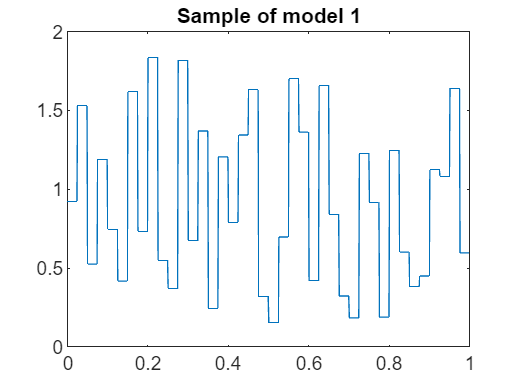

% Mesh to define random field
N = 40;

% Set a value for sigma
sigma = 0.5;

% Interval on which we evaluate the random field
l = 4;
I = N*2^l; % Mesh for numerical approximation of discr. PDE

x = linspace(0, 1, I);

Y = a_constant_coeff(x, N, sigma);

plot(x, Y);
title('Sample of model 1')

`Model 2: Log normal`

No we would like to sample the random field defined by

                                
$$a(x,w) = \exp(\kappa(x,w))$$


where $\kappa(x,w)$ is a stationary Gaussian random field with mean zero and the Mátern covariance function

                
$$C(x,y) = \sigma^2\frac{1}{\Gamma(\nu)2^{\nu-1}}\left(\sqrt{2\nu}\frac{|x-y|}{\rho}\right)^\nu K_\nu\left(\sqrt{2\nu}\frac{|x-y|}{\rho}\right)$$


where $\Gamma$ is the Gamma function and $K_\nu$ is the modified Bessel function of the second kind. We will look at special cases

- `Case: `$\nu=0.5$, $C(x,y)=\sigma^2\exp\left(-\frac{|x-y|}{\rho}\right)$

- `Case: `$\nu=1.5$, $C(x,y)=\sigma^2\left(1+\frac{\sqrt{3}|x-y|}{\rho}\right)\exp\left(-\frac{\sqrt{3}|x-y|}{\rho}\right)$

- `Case: `$\nu=2.5$, $C(x,y)=\sigma^2\left(1+\frac{\sqrt{5}|x-y|}{\rho}+\frac{\sqrt{3}|x-y|}{\rho^2}\right)\exp\left(-\frac{\sqrt{5}|x-y|}{\rho}\right)$

- `Case: `$\nu\to\infty
$, $C(x,y)=\sigma^2\exp\left(-\frac{|x-y|^2}{2\rho^2}\right)$

Moreover we choose $\rho=0.1$ and $\sigma^2=2$.

- `Possible approximation: Cholesky/SV decomposition`

We will now sample these covarianc functions using a Grid on $[0,1]$. For that we need to construction covariance matrices given an input mesh $X$.

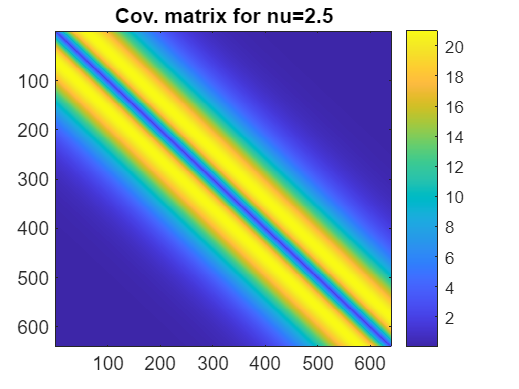

nu = 2.5;
X = linspace(0, 1, I);
C = Matern_specialcases_only(X, nu);

% We plot the corresponding covariance matrix using a color plot
imagesc(C)
title('Cov. matrix for nu=2.5')
colorbar

Now we can do a Cholesky-Decomposition (for example, could also use singular value decomp.) to get the matrix $A$ such that $C=AA^T$.

if (nu == 0.5 | nu == 1.5)
    A = chol(C,'lower');
end

if (nu == 2.5 | nu == 'infinity')
    [U,S,V] = svd(C);
    S_sqrt = sqrt(S);
    A = U*S_sqrt;
end

And finally we can sample the random field $\kappa(x,w)$, namely $X_h$, on the grid by sampling a standart Gaussian $Z\sim\mathcal{N}(0,I)$ and get the sample of our random field (since we have mean zero) by $X_h = AZ$.

Z = normrnd(0, 1, [I 1]);
X_h = exp(mtimes(A, Z));

We can also plot this

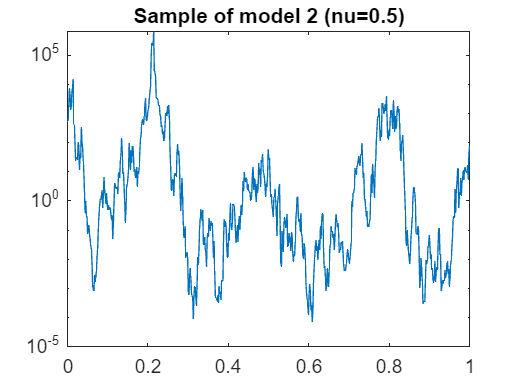

semilogy(X, X_h);
title('Sample of model 2 (nu=0.5)')

I also implemented this procedure in a single function.

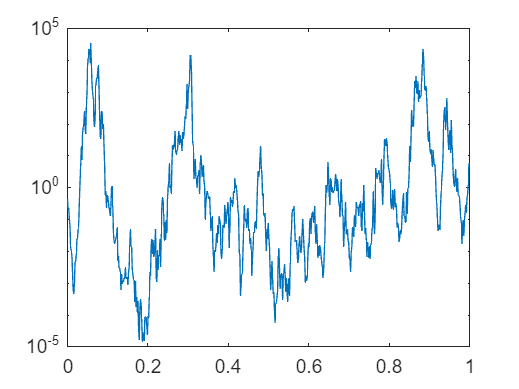

Y = a_matern(X, nu);
semilogy(X, Y)

             2. `Possible approximation: Karhunen-Loève expansion`

Now we want to sample the random field using a Karhunen-Loève expansion with $N$ terms

                            
$$\kappa(x,w)\approx\sum_{n=1}^N\sqrt{\lambda_n}Y_n(w)e_n(w)$$


where $\{Y_n\}$ is a set of i.i.d. standart Gaussians. To find the eigenfunctions and eigenvalues of our covariance function $C$, we solve the eigenproblem

                            
$$\int_0^1 C(x,y)e_n(y)dy = \lambda_ne_n(x)$$


We do this by discretizing $C$ as a matrix by evaluating the function ... 